Es = 1; 
N = 1e5;
p1 = 0.5;


function bit_vec = BitVec(Nbit,pbit)
    bit_vec = rand(1,Nbit) < pbit ;
end

function sym_vec = QAM4SymVec(bit_vec,Es)
    L = length(bit_vec);
    sym_vec = zeros(1,L/2) ;
    for i = 1 : L/2
        a = bit_vec(2*i-1);
        b = bit_vec(2*i);
        s = (-1)^a + (-1)^b * 1i ;
        sym_vec(i) = s / abs(s) * sqrt(Es); 
    end 
end


function [sym_vec_tx,yvec] = QAM4_Rec(SNRb, Es, Nbit, pbit)
    Eb = Es / 2;
    N0 = Eb / SNRb;
    
    B = BitVec(Nbit,pbit);
    sym_vec_tx = QAM4SymVec(B,Es);
    Ns = length(sym_vec_tx);

    CSCN = randn(1,Ns) + randn(1,Ns) * 1i;
    yvec = sym_vec_tx + CSCN * sqrt(N0/2);
end 


function svecdec=QAM4_SymMAPDec(yvec, SNRb, Es, pbit)
    svecdec = zeros(1,length(yvec));
    P = [ (1-pbit)^2 , (1-pbit)*pbit , (pbit)^2 , (1-pbit)*pbit ];
    
    Eb = Es / 2;
    N0 = Eb / SNRb; 
    
    % FIX: Swapped P(2)/P(3) to P(3)/P(2) to align 'Left/Right' ratio 
    % with 'Bottom/Top' logic used in bias_Im
    bias_Re = N0/2 * log(P(3)/P(2)); 
    bias_Im = N0/2 * log(P(2)/P(1));

    for i = 1 : length(yvec)
        y = yvec(i);
        a = real(y);
        b = imag(y);
        
        s_raw = (-1)^((a >= bias_Re)+1) + (-1)^((b >= bias_Im)+1) * 1i;
        
        svecdec(i) = s_raw / abs(s_raw) * sqrt(Es);
    end
end


function ser=CompSER(sym_vec_tx,svecdec)
    ser = 1 - sum(abs(sym_vec_tx - svecdec) < 1e-5) / length(sym_vec_tx);
end


SNR_s = -6 : 6;
SER = zeros(1,length(SNR_s));

for i = 1 : length(SNR_s)
    SNRb_DB = SNR_s(i);
    SNRb = 10^(SNRb_DB/10);
    [S,Y] = QAM4_Rec(SNRb, Es, N, p1);
    S_dec = QAM4_SymMAPDec(Y, SNRb, Es, p1);
    
    ser = CompSER(S,S_dec);
    SER(i) = ser;
end 


disp('SNR (dB):');

SNR (dB):


disp(SNR_s);

    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6



disp('SER:');

SER:


disp(SER);

    0.4267    0.3794    0.3377    0.2907    0.2451    0.1974    0.1530    0.1087    0.0727    0.0442    0.0255    0.0125    0.0049



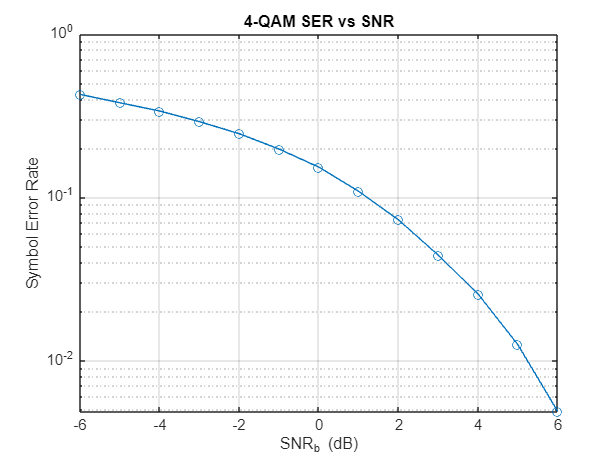

figure
semilogy(SNR_s, SER, '-o');
grid on;
title('4-QAM SER vs SNR');
xlabel('SNR_b (dB)');
ylabel('Symbol Error Rate');

p1_s = 0.01: 0.01 : 0.99;
SER = zeros(1,length(p1_s));
SNRb_DB = -3;

for i = 1 : length(p1_s)
    p1 = p1_s(i);
    SNRb = 10^(SNRb_DB/10);
    [S,Y] = QAM4_Rec(SNRb, Es, N, p1);
    S_dec = QAM4_SymMAPDec(Y, SNRb, Es, p1);
    
    ser = CompSER(S,S_dec);
    SER(i) = ser;
end 


disp('p1:');

p1:


disp(p1_s);

    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900    0.5000    0.5100    0.5200    0.5300    0.5400    0.5500    0.5600    0.5700    0.5800    0.5900    0.6000    0.6100    0.6200    0.6300    0.6400    0.6500    0.6600    0.6700    0.6800    0.6900    0.7000    0.7100    0.7200    0.7300    0.7400    0.7500    0.7600    0.7700    0.7800    0.7900    0.8000    0.8100    0.8200    0.8300    0.8400    0.8500    0.8600    0.8700    0.8800    0.8900    0.9000    0.9100    0.9200    0.9300    0.9400    0.9500    0.9600    0.9700    0.9800    0.9900



disp('SER:');

SER:


disp(SER);

    0.0188    0.0386    0.0556    0.0712    0.0875    0.0987    0.1124    0.1248    0.1326    0.1442    0.1542    0.1631    0.1725    0.1820    0.1887    0.1974    0.2028    0.2090    0.2174    0.2216    0.2238    0.2313    0.2354    0.2431    0.2447    0.2503    0.2516    0.2546    0.2570    0.2639    0.2667    0.2680    0.2713    0.2748    0.2746    0.2784    0.2788    0.2805    0.2808    0.2862    0.2827    0.2839    0.2912    0.2899    0.2921    0.2899    0.2924    0.2911    0.2889    0.2923    0.2908    0.2912    0.2910    0.2897    0.2901    0.2909    0.2908    0.2841    0.2853    0.2833    0.2800    0.2826    0.2800    0.2798    0.2752    0.2698    0.2707    0.2692    0.2646    0.2599    0.2610    0.2569    0.2541    0.2476    0.2443    0.2399    0.2401    0.2299    0.2298    0.2210    0.2157    0.2090    0.2038    0.1975    0.1918    0.1834    0.1748    0.1634    0.1533    0.1444    0.1351    0.1233    0.1158    0.1014    0.0859    0.0712    0.0538    0.0384    0.0205



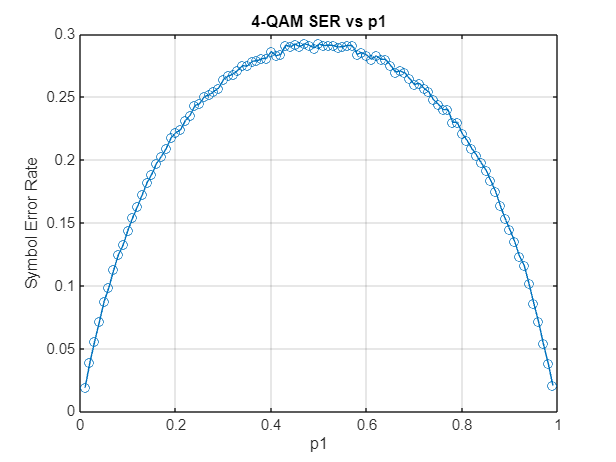

figure
plot(p1_s, SER, '-o');
grid on;
title('4-QAM SER vs p1');
xlabel('p1');
ylabel('Symbol Error Rate');

Es = 1; 
Nsym = 1e5;

function sym_vec = QAM8SymVec(Nsym, Es)
    sqEs = sqrt(Es);
    
    S0 =  sqEs + 1i*(sqEs/2);
    S1 =  sqEs - 1i*(sqEs/2);
    S2 =  (sqEs/2) + 1i*0;
    S3 =  0 + 1i*(sqEs/2);
    S4 =  0 - 1i*(sqEs/2);
    S5 = -(sqEs/2) + 1i*0;
    S6 = -sqEs + 1i*(sqEs/2);
    S7 = -sqEs - 1i*(sqEs/2);
    
    Constellation = [S0, S1, S2, S3, S4, S5, S6, S7];
    
    indices = randi([1, 8], 1, Nsym);
    sym_vec = Constellation(indices);
end

function yvec = QAM8_Rec(sym_vec8, SNRb, Es)
    E_avg = 0.75 * Es;
    Eb = E_avg / 3;
    N0 = Eb / SNRb;
    
    Ns = length(sym_vec8);
    noise = (randn(1, Ns) + 1i*randn(1, Ns)) * sqrt(N0/2);
    yvec = sym_vec8 + noise;
end 

function svecdec = QAM8_SymMAPDec(yvec, Es)
    sqEs = sqrt(Es);
    Constellation = [ ...
         (sqEs + 1i*sqEs/2), ...
         (sqEs - 1i*sqEs/2), ...
         (sqEs/2 + 1i*0), ...
         (0 + 1i*sqEs/2), ...
         (0 - 1i*sqEs/2), ...
         (-sqEs/2 + 1i*0), ...
         (-sqEs + 1i*sqEs/2), ...
         (-sqEs - 1i*sqEs/2) ];
         
    svecdec = zeros(1, length(yvec));
    
    for i = 1 : length(yvec)
        y = yvec(i);
        [~, idx] = min(abs(y - Constellation).^2);
        svecdec(i) = Constellation(idx);
    end
end

SNR_dB = -25 : 1 : 0;
SER_Sim = zeros(1, length(SNR_dB));
SER_Theory = zeros(1, length(SNR_dB));

for i = 1 : length(SNR_dB)
    snr_db_val = SNR_dB(i);
    SNRb = 10^(snr_db_val/10);
    
    S = QAM8SymVec(Nsym, Es);
    Y = QAM8_Rec(S, SNRb, Es);
    S_dec = QAM8_SymMAPDec(Y, Es);
    
    SER_Sim(i) = CompSER(S, S_dec);
    SER_Theory(i) = 3 * 0.5 * erfc(sqrt(SNRb)/sqrt(2));
end 


disp('SNR (dB):'); disp(SNR_dB);

SNR (dB):
   -25   -24   -23   -22   -21   -20   -19   -18   -17   -16   -15   -14   -13   -12   -11   -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0



disp('SER Sim:'); disp(SER_Sim);

SER Sim:
    0.8510    0.8459    0.8423    0.8397    0.8339    0.8293    0.8258    0.8188    0.8128    0.8009    0.7917    0.7788    0.7677    0.7523    0.7352    0.7179    0.6924    0.6646    0.6366    0.6064    0.5695    0.5260    0.4852    0.4328    0.3815    0.3251



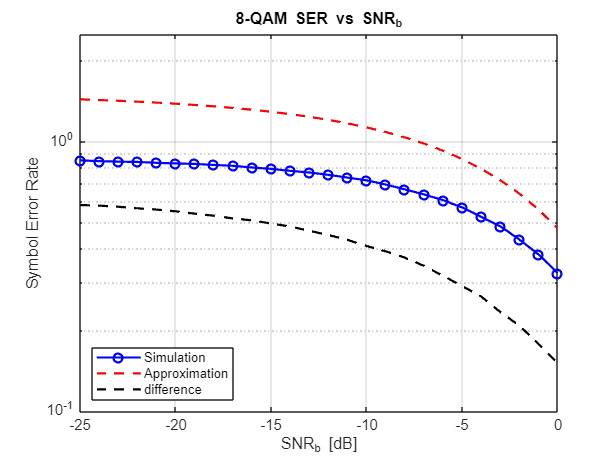


figure;
semilogy(SNR_dB, SER_Sim, 'bo-', 'LineWidth', 1.5);
hold on;
semilogy(SNR_dB, SER_Theory, 'r--', 'LineWidth', 1.5);
semilogy(SNR_dB, (SER_Theory - SER_Sim), 'black--', 'LineWidth', 1.5);
grid on;
title('8-QAM SER vs SNR_b');
xlabel('SNR_b [dB]');
ylabel('Symbol Error Rate');
legend('Simulation', 'Approximation','difference', 'Location', 'southwest');
axis([-25 0 1e-1 2.5]);

Nsc = 128;
Ncp = 8;

function s = QAM4_Mapper(bits)
    b = bits(1)*2 + bits(2);
    scale = 1/sqrt(2);
    switch b
        case 0 % 00
            s = (1 + 1i) * scale;
        case 1 % 01
            s = (1 - 1i) * scale;
        case 3 % 11
            s = (-1 - 1i) * scale;
        case 2 % 10
            s = (-1 + 1i) * scale;
    end
end
function dec_bits = QAM4_Decode(sym_est_vec)
    L = length(sym_est_vec);
    dec_bits = zeros(1, 2*L);
    for i = 1:L
        re = real(sym_est_vec(i));
        im = imag(sym_est_vec(i));
        if re >= 0 && im >= 0
            b = [0 0];
        elseif re >= 0 && im < 0
            b = [0 1];
        elseif re < 0 && im >= 0
            b = [1 0];
        else
            b = [1 1];
        end
        dec_bits(2*i-1 : 2*i) = b;
    end
end


function s = QAM8_Mapper(bits)
    Es = 1;
    sqEs = sqrt(Es);
    
    dec = bits(1)*4 + bits(2)*2 + bits(3);
    
    switch dec
        case 0 % 000 -> S3
            s = 0 + 1i*(sqEs/2);
        case 1 % 001 -> S0
            s = sqEs + 1i*(sqEs/2);
        case 3 % 011 -> S1
            s = sqEs - 1i*(sqEs/2);
        case 2 % 010 -> S4
            s = 0 - 1i*(sqEs/2);
        case 6 % 110 -> S7
            s = -sqEs - 1i*(sqEs/2);
        case 7 % 111 -> S6
            s = -sqEs + 1i*(sqEs/2);
        case 5 % 101 -> S5
            s = -(sqEs/2) + 1i*0;
        case 4 % 100 -> S2
            s = (sqEs/2) + 1i*0;
    end
end

function dec_bits = QAM8_Decode(sym_est_vec)
    Es = 1; sqEs = sqrt(Es);
    S = [ (0+1i*sqEs/2), (sqEs+1i*sqEs/2), (sqEs-1i*sqEs/2), (0-1i*sqEs/2), ...
          (-sqEs-1i*sqEs/2), (-sqEs+1i*sqEs/2), (-sqEs/2), (sqEs/2) ];
    % 1:000, 2:001, 3:011, 4:010, 5:110, 6:111, 7:101, 8:100
    BitsMap = [0 0 0; 0 0 1; 0 1 1; 0 1 0; 1 1 0; 1 1 1; 1 0 1; 1 0 0];
    
    L = length(sym_est_vec);
    dec_bits = zeros(1, 3*L);
    
    for i = 1:L
        val = sym_est_vec(i);
        [~, idx] = min(abs(val - S).^2); 
        dec_bits(3*i-2 : 3*i) = BitsMap(idx, :);
    end
end

% --- 1. OFDM Modulator (Item 2.2.1) ---
function xofdm = OFDM_Mod(bit_stream, Nsc, Ncp, constellation)
    if strcmp(constellation, 'BPSK')
        M_bits = 1;
        Es = 1; 
        map_func = @(b) (2*b - 1) * sqrt(Es); 
        
    elseif strcmp(constellation, '4QAM')
        M_bits = 2;
        Es = 1;
        map_func = @QAM4_Mapper;
        
    elseif strcmp(constellation, '8QAM')
        M_bits = 3;
        Es = 1;
        map_func = @QAM8_Mapper;
    else
        error('Unknown constellation');
    end
    bits_per_ofdm = Nsc * M_bits;
    L = length(bit_stream);
    remainder = mod(L, bits_per_ofdm);

    if remainder ~= 0
        padding = randi([0 1], 1, bits_per_ofdm - remainder);
        bit_stream = [bit_stream, padding];
    end
    
    num_bits = length(bit_stream);
    num_syms = num_bits / M_bits;     % Number of constellation symbols
    num_ofdm = num_syms / Nsc;        % Number of OFDM symbols (m)
    
    const_symbols = zeros(1, num_syms);
    for i = 1:num_syms
        b_idx = (i-1)*M_bits + 1;
        bits = bit_stream(b_idx : b_idx+M_bits-1);
        const_symbols(i) = map_func(bits);
    end

    sym_matrix = reshape(const_symbols, Nsc, num_ofdm).'; 
    
    sym_matrix_T = sym_matrix.'; % Size Nsc x m
    time_matrix_T = ifft(sym_matrix_T) * sqrt(Nsc) ;% Nsc x m
    
    cp_part = time_matrix_T(end-Ncp+1:end, :);
    ofdm_syms_T = [cp_part; time_matrix_T]; % Size (Nsc+Ncp) x m
    
    xofdm = ofdm_syms_T(:).'; 
end



% --- 2. Wireless Channel (Item 2.2.2) ---
function [r1ofdm, r2ofdm] = Wireless_Channel(xofdm, N0)
    % Constants
    omega0 = 2 * pi * sqrt(2);
    
    % Channel 1 Def
    a1_vals = [8.1, 2.3, 5, 2.3, 1.9, 0.5];
    a1 = (1/10.2424) * a1_vals;
    L1 = length(a1);
    h1 = zeros(1, L1);
    for n = 0:L1-1
        h1(n+1) = a1(n+1) * exp(1i * omega0 * n);
    end
    
    % Channel 2 Def
    a2_vals = [8.1, 2.3, 5, 2.3, 1.9, 0.5, 3, 1.1, 0.9, 0.35, 1.5, 2, 3];
    a2 = (1/11.4648) * a2_vals;
    L2 = length(a2);
    h2 = zeros(1, L2);
    for n = 0:L2-1
        h2(n+1) = a2(n+1) * exp(1i * omega0 * n);
    end
    
    % Apply Convolutions
    r1_conv = conv(xofdm, h1);
    r2_conv = conv(xofdm, h2);
    
    % Truncate to length of input
    Lx = length(xofdm);
    r1_trunc = r1_conv(1:Lx);
    r2_trunc = r2_conv(1:Lx);
    
    % Generate Noise
    % CN(0, N0) -> Real/Imag parts have var N0/2
    noise = (randn(1, Lx) + 1i*randn(1, Lx)) * sqrt(N0/2);
    
    % Add Noise
    r1ofdm = r1_trunc + noise;
    r2ofdm = r2_trunc + noise;
end

% --- 3. OFDM Demodulator (Item 2.2.3) ---
function dec_bits = OFDM_Demod(rvec, Nsc, Ncp, constellation, Channel)
    omega0 = 2 * pi * sqrt(2);
    if Channel == 1
        a_vals = [8.1, 2.3, 5, 2.3, 1.9, 0.5];
        norm_fac = 1/10.2424;
    else
        a_vals = [8.1, 2.3, 5, 2.3, 1.9, 0.5, 3, 1.1, 0.9, 0.35, 1.5, 2, 3];
        norm_fac = 1/11.4648;
    end

    a = norm_fac * a_vals;
    L = length(a);
    h = zeros(1, L);

    for n = 0:L-1
        h(n+1) = a(n+1) * exp(1i * omega0 * n);
    end
    H_k = fft(h, Nsc);
    
    Nsym = Nsc + Ncp;
    num_samples = length(rvec);
    m = floor(num_samples / Nsym);
    r_matrix = reshape(rvec(1:m*Nsym), Nsym, m);
    r_no_cp = r_matrix(Ncp+1:end, :); % Size Nsc x m
    y_freq = fft(r_no_cp) / sqrt(Nsc); % Size Nsc x m
    H_k_mat = repmat(H_k.', 1, m); % Ensure H_k is column
    sym_est_mat = y_freq ./ H_k_mat;
    
    % Serialize to vector of symbols
    % sym_est_vec = sym_est_mat.'; % Transpose to get row-by-row
    % sym_est_vec = sym_est_vec(:).';
    sym_est_vec = sym_est_mat(:).';
    
    % 6. Demap / Decode Bits
    dec_bits = [];
    if strcmp(constellation, 'BPSK')
        dec_bits = real(sym_est_vec) > 0;
    elseif strcmp(constellation, '4QAM')
        dec_bits = QAM4_Decode(sym_est_vec);
    elseif strcmp(constellation, '8QAM')
        dec_bits = QAM8_Decode(sym_est_vec);
    end
end

Nbit = 200;
p1 = 0.5;
bit_stream = BitVec(Nbit,p1)

bit_stream = 1×200 logical array
   0   1   1   1   1   1   0   0   1   1   0   1   0   1   0   1   0   0   1   0   1   1   1   1   0   1   0   1   1   1   1   1   1   0   1   0   1   0   1   1   1   1   1   1   0   1   1   1   1   0


constellation = '4QAM'

constellation = '4QAM'

xofdm = OFDM_Mod(bit_stream, Nsc, Ncp, constellation)

xofdm =   -0.4173 + 0.4477i  -0.3288 + 0.2167i   0.4282 - 1.9938i  -1.0307 - 0.6355i  -0.4070 - 0.4517i  -0.2101 - 0.1862i  -0.6881 - 0.0555i  -1.8071 + 1.1048i   0.1250 - 1.1250i  -0.3161 - 0.1907i   0.1547 - 0.7064i   0.4105 + 0.6932i   0.9811 + 0.4025i   1.1570 + 0.5464i  -1.6164 + 0.9947i   0.3023 - 0.5094i   0.1818 + 0.5367i  -0.0437 - 0.1402i  -0.7467 + 0.1431i   0.5476 + 0.4570i   0.9275 - 1.2821i  -0.1078 + 0.0919i  -0.4901 - 0.2960i   0.0588 + 0.7791i  -0.6402 + 0.7652i  -1.2821 - 0.3727i  -0.0292 + 0.1757i   1.4825 - 0.1237i   1.6711 + 0.0499i   0.1497 + 0.0636i   0.3168 - 0.1108i   1.7595 - 0.5386i   0.0039 + 0.1760i  -0.1241 - 0.6453i   0.2969 - 0.0353i   0.2461 - 1.0810i   0.3126 + 0.0126i   1.5180 - 1.3616i  -0.2167 - 0.7634i  -0.2041 + 1.0417i  -0.2500 + 0.5000i   0.3048 - 0.2681i   0.7641 - 0.9380i  -0.2135 - 0.2908i   0.2221 - 0.1903i  -0.6104 + 0.1492i  -0.3005 - 0.7286i   0.2734 - 0.0403i   0.2891 - 0.5647i   0.4329 + 0.7080i


N0 = 1e-1;
xofdm

xofdm =   -0.4173 + 0.4477i  -0.3288 + 0.2167i   0.4282 - 1.9938i  -1.0307 - 0.6355i  -0.4070 - 0.4517i  -0.2101 - 0.1862i  -0.6881 - 0.0555i  -1.8071 + 1.1048i   0.1250 - 1.1250i  -0.3161 - 0.1907i   0.1547 - 0.7064i   0.4105 + 0.6932i   0.9811 + 0.4025i   1.1570 + 0.5464i  -1.6164 + 0.9947i   0.3023 - 0.5094i   0.1818 + 0.5367i  -0.0437 - 0.1402i  -0.7467 + 0.1431i   0.5476 + 0.4570i   0.9275 - 1.2821i  -0.1078 + 0.0919i  -0.4901 - 0.2960i   0.0588 + 0.7791i  -0.6402 + 0.7652i  -1.2821 - 0.3727i  -0.0292 + 0.1757i   1.4825 - 0.1237i   1.6711 + 0.0499i   0.1497 + 0.0636i   0.3168 - 0.1108i   1.7595 - 0.5386i   0.0039 + 0.1760i  -0.1241 - 0.6453i   0.2969 - 0.0353i   0.2461 - 1.0810i   0.3126 + 0.0126i   1.5180 - 1.3616i  -0.2167 - 0.7634i  -0.2041 + 1.0417i  -0.2500 + 0.5000i   0.3048 - 0.2681i   0.7641 - 0.9380i  -0.2135 - 0.2908i   0.2221 - 0.1903i  -0.6104 + 0.1492i  -0.3005 - 0.7286i   0.2734 - 0.0403i   0.2891 - 0.5647i   0.4329 + 0.7080i


[r1ofdm, r2ofdm] = Wireless_Channel(xofdm, N0)

r1ofdm =    0.2269 + 0.2634i  -0.6610 + 0.3392i   0.6525 - 1.8416i  -0.9291 + 0.0585i  -1.0559 - 1.2210i  -0.4728 + 0.3155i  -0.9398 - 0.0705i  -1.0116 + 1.2020i   0.0715 - 0.7102i  -0.5093 + 0.9344i  -0.7064 - 1.2797i   0.6763 + 0.7503i   0.3544 - 0.0850i   1.4041 + 0.2466i  -1.3171 + 0.5339i   0.5674 - 0.8542i   0.0197 + 1.5958i  -0.5017 - 1.0940i  -0.0285 + 0.2199i  -0.1277 + 0.2364i   0.5098 - 0.4680i   0.0412 + 0.2016i  -1.3162 - 0.4788i   0.2164 + 0.7205i  -0.9928 + 0.4417i  -0.3109 - 0.2166i   0.2759 + 0.5509i   1.2390 - 0.0468i   1.2753 + 0.0782i  -0.0167 - 0.0667i   0.5060 - 0.3092i   1.3291 - 0.1650i  -0.5842 + 0.1481i   0.4858 - 1.1781i  -0.1238 + 0.2757i  -0.4651 - 1.3154i   0.4159 - 0.0235i   0.8983 - 1.5671i   0.1677 - 0.5166i  -0.5172 + 0.1133i  -0.4109 + 0.4819i   0.6999 - 0.4427i   0.4168 - 0.5479i  -0.8119 - 0.2421i   0.6945 - 0.4482i  -0.8039 + 0.5513i  -0.0155 - 1.1251i   0.6165 + 0.4108i   0.0540 - 0.5773i   0.5820 + 0.9087i


r2ofdm =    0.2621 + 0.2257i  -0.6363 + 0.3353i   0.6021 - 1.6952i  -0.8485 + 0.0550i  -0.9761 - 1.1089i  -0.4668 + 0.2831i  -0.7342 - 0.1910i  -0.8045 + 1.0997i  -0.0371 - 0.0804i  -0.2851 + 0.7722i  -0.5971 - 0.9432i   0.6546 + 0.5561i   0.7474 - 0.0755i   1.3803 + 0.1159i  -1.0677 + 0.4654i   0.2215 - 0.9855i  -0.0800 + 1.5822i  -0.8237 - 1.3193i   0.1074 + 0.0332i  -0.9530 + 0.5726i   1.0282 - 0.9486i  -0.3720 + 0.6977i  -1.2969 - 0.9711i   0.3325 + 0.9867i  -0.8702 + 0.1175i   0.2886 - 0.2130i  -0.3749 + 1.2479i   1.2220 - 0.4467i   1.3333 + 0.3295i  -0.0479 - 0.1963i   0.6334 - 0.4814i   1.3845 + 0.2614i  -0.4856 - 0.3951i   0.1505 - 0.8395i  -0.7574 + 0.0054i  -0.2197 - 1.2386i   0.2577 + 0.4545i   0.1889 - 1.2407i   0.1520 - 0.4958i  -0.3204 + 0.2210i  -0.0858 + 0.3010i   0.8730 - 0.0051i  -0.0476 - 0.6186i  -0.5700 - 0.1092i   0.7675 - 0.1804i  -0.7091 + 0.0954i   0.1213 - 0.9349i   0.6474 + 0.1876i  -0.2681 - 0.2841i   0.7982 + 0.6171i


trunc = 20

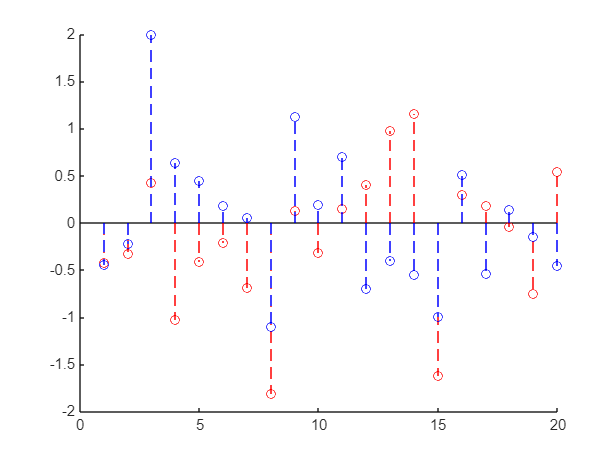

for vec = [xofdm,r1ofdm, r2ofdm]'
    figure ;
    trunc = 20
    vec;
    hold on 
    stem(1:trunc,real(vec(1:trunc)),"r--")
    stem(1:trunc,imag(vec(1:trunc)),"b--")
    hold off
end



a1= [8.1, 2.3, 5, 2.3, 1.9, 0.5];
norm_fac_1 = 1/10.2424;

a2 = [8.1, 2.3, 5, 2.3, 1.9, 0.5, 3, 1.1, 0.9, 0.35, 1.5, 2, 3];
norm_fac_2 = 1/11.4648;

figure
Nk = 100

Nk = 100

h1 = ifft(a1,Nk)

h1 =    0.2010 + 0.0000i   0.1993 + 0.0183i   0.1943 + 0.0359i   0.1863 + 0.0521i   0.1756 + 0.0663i   0.1627 + 0.0782i   0.1483 + 0.0872i   0.1329 + 0.0933i   0.1173 + 0.0964i   0.1020 + 0.0966i   0.0876 + 0.0941i   0.0746 + 0.0894i   0.0633 + 0.0828i   0.0541 + 0.0749i   0.0469 + 0.0662i   0.0418 + 0.0571i   0.0387 + 0.0481i   0.0372 + 0.0397i   0.0371 + 0.0320i   0.0382 + 0.0253i   0.0399 + 0.0197i   0.0421 + 0.0151i   0.0444 + 0.0115i   0.0466 + 0.0088i   0.0485 + 0.0067i   0.0500 + 0.0050i   0.0511 + 0.0036i   0.0519 + 0.0022i   0.0523 + 0.0007i   0.0526 - 0.0010i   0.0529 - 0.0030i   0.0533 - 0.0052i   0.0540 - 0.0077i   0.0551 - 0.0104i   0.0565 - 0.0131i   0.0585 - 0.0157i   0.0610 - 0.0181i   0.0639 - 0.0201i   0.0672 - 0.0218i   0.0708 - 0.0228i   0.0746 - 0.0233i   0.0784 - 0.0232i   0.0821 - 0.0224i   0.0857 - 0.0211i   0.0890 - 0.0192i   0.0919 - 0.0167i   0.0944 - 0.0139i   0.0964 - 0.0107i   0.0978 - 0.0073i   0.0987 - 0.0037i


h2 = ifft(a2,Nk)

h2 =    0.3195 + 0.0000i   0.2974 + 0.0823i   0.2398 + 0.1395i   0.1685 + 0.1573i   0.1089 + 0.1379i   0.0781 + 0.0982i   0.0787 + 0.0607i   0.0988 + 0.0431i   0.1191 + 0.0503i   0.1234 + 0.0734i   0.1060 + 0.0957i   0.0743 + 0.1021i   0.0436 + 0.0869i   0.0288 + 0.0566i   0.0360 + 0.0258i   0.0598 + 0.0095i   0.0862 + 0.0151i   0.0999 + 0.0386i   0.0924 + 0.0669i   0.0656 + 0.0849i   0.0310 + 0.0827i   0.0033 + 0.0604i  -0.0070 + 0.0273i   0.0018 - 0.0032i   0.0226 - 0.0208i   0.0440 - 0.0225i   0.0564 - 0.0138i   0.0570 - 0.0043i   0.0503 - 0.0021i   0.0448 - 0.0094i   0.0473 - 0.0217i   0.0593 - 0.0309i   0.0760 - 0.0305i   0.0892 - 0.0193i   0.0921 - 0.0023i   0.0832 + 0.0120i   0.0674 + 0.0166i   0.0529 + 0.0096i   0.0466 - 0.0049i   0.0508 - 0.0191i   0.0617 - 0.0264i   0.0724 - 0.0251i   0.0766 - 0.0187i   0.0734 - 0.0143i   0.0669 - 0.0176i   0.0649 - 0.0291i   0.0734 - 0.0437i   0.0933 - 0.0526i   0.1188 - 0.0484i   0.1402 - 0.0291i


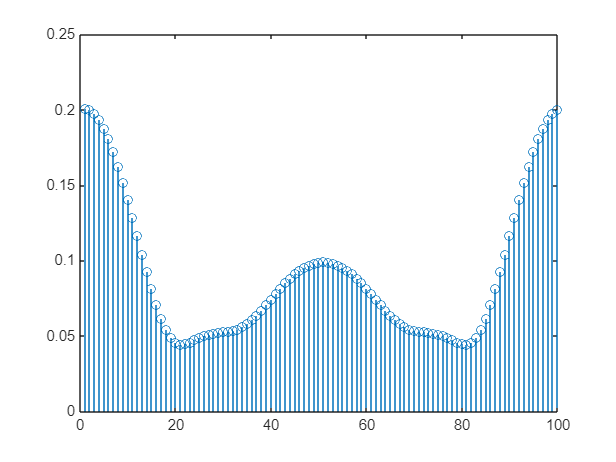

stem(1:Nk,abs(h1))

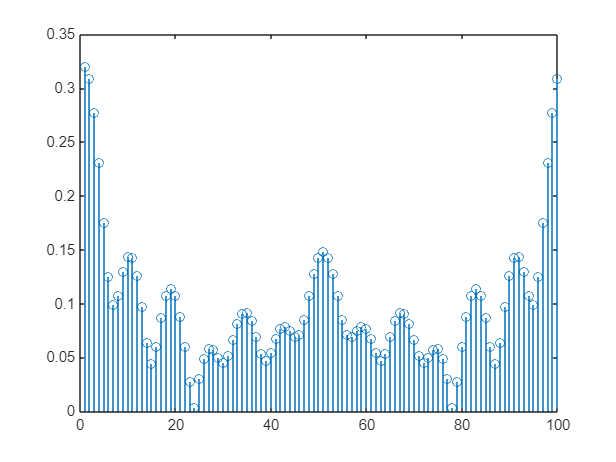

stem(1:Nk,abs(h2))

r1_rec = OFDM_Demod(r1ofdm, Nsc, Ncp, constellation, 1);
r2_rec = OFDM_Demod(r2ofdm, Nsc, Ncp, constellation, 2);

% --- TRUNCATE HERE ---
r1_rec = r1_rec(1:Nbit); 
r2_rec = r2_rec(1:Nbit);

% Calculate Bit Error Rate (BER)
BER1 = sum(abs(bit_stream - r1_rec)) / Nbit

BER1 = 0.0250

BER2 = sum(abs(bit_stream - r2_rec)) / Nbit

BER2 = 0.0550

%% OFDM Performance Evaluation Script
clear; close all; clc;

% --- 1. System Parameters ---
Nsc = 128;           % Number of subcarriers (Standard value, adjust if needed)
Ncp = 16;           % Cyclic Prefix length (Standard value, adjust if needed)
N_OFDM_Syms = 10000;% Number of OFDM symbols per iteration (from Sec 2.2.5)
EbN0_dB = -10:2:20; % Eb/N0 range in dB (from Sec 2.2.6)

% Constellation settings
constellations = {'BPSK', '4QAM', '8QAM'};
bits_per_symbol = [1, 2, 3]; % log2(M) for BPSK, 4QAM, 8QAM

% Pre-allocate BER storage
% Rows: Different constellations, Cols: Different Eb/N0 values
BER_Ch1 = zeros(length(constellations), length(EbN0_dB));
BER_Ch2 = zeros(length(constellations), length(EbN0_dB)); 

%% --- 2. Simulation Loop ---

fprintf('Starting Simulation...\n');

Starting Simulation...



for c_idx = 1:length(constellations)
    current_const = constellations{c_idx};
    M = 2^bits_per_symbol(c_idx); % Constellation order
    k = bits_per_symbol(c_idx);   % Bits per subcarrier
    
    Nbits_total = N_OFDM_Syms * Nsc * k;
    fprintf('Testing %s (%d bits)... ', current_const, Nbits_total);
    
    bit_stream = rand(1, Nbits_total) > 0.5; 
    xofdm = OFDM_Mod(bit_stream, Nsc, Ncp, current_const);
    sig_power = mean(abs(xofdm).^2); 
    
    for snr_idx = 1:length(EbN0_dB)
        ebn0_lin = 10^(EbN0_dB(snr_idx)/10);
        N0 = sig_power / (ebn0_lin * k);

        [r1ofdm, r2ofdm] = Wireless_Channel(xofdm, N0);

        rx_bits_1 = OFDM_Demod(r1ofdm, Nsc, Ncp, current_const, 1);
        
        rx_bits_1 = rx_bits_1(1:Nbits_total);
        
        num_err_1 = sum(abs(bit_stream - rx_bits_1));
        BER_Ch1(c_idx, snr_idx) = num_err_1 / Nbits_total;
        
        if strcmp(current_const, 'BPSK') || strcmp(current_const, '4QAM')

            rx_bits_2 = OFDM_Demod(r2ofdm, Nsc, Ncp, current_const, 2);
            rx_bits_2 = rx_bits_2(1:Nbits_total); % Truncate
            
            num_err_2 = sum(abs(bit_stream - rx_bits_2));
            BER_Ch2(c_idx, snr_idx) = num_err_2 / Nbits_total;
        end
    end
    fprintf('Done.\n');
end

Testing BPSK (1280000 bits)... 

Done.


Testing 4QAM (2560000 bits)... 

Done.


Testing 8QAM (3840000 bits)... 

Done.


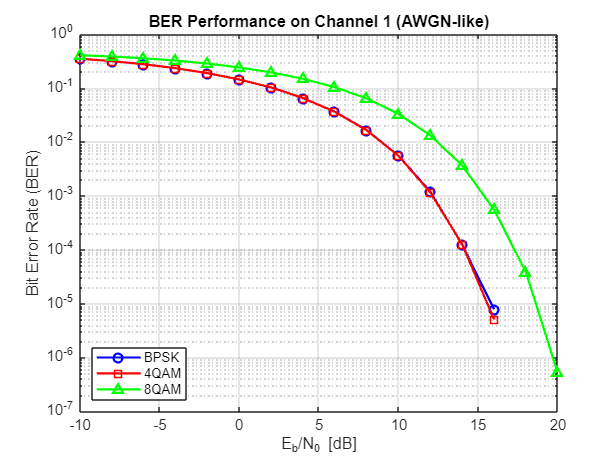

figure('Name', 'BER vs Eb/N0 - Channel 1');
semilogy(EbN0_dB, BER_Ch1(1, :), 'b-o', 'LineWidth', 1.5, 'DisplayName', 'BPSK');
hold on;
semilogy(EbN0_dB, BER_Ch1(2, :), 'r-s', 'LineWidth', 1.5, 'DisplayName', '4QAM');
semilogy(EbN0_dB, BER_Ch1(3, :), 'g-^', 'LineWidth', 1.5, 'DisplayName', '8QAM');
grid on;
xlabel('E_b/N_0 [dB]');
ylabel('Bit Error Rate (BER)');
title('BER Performance on Channel 1 (AWGN-like)');
legend('Location', 'southwest');

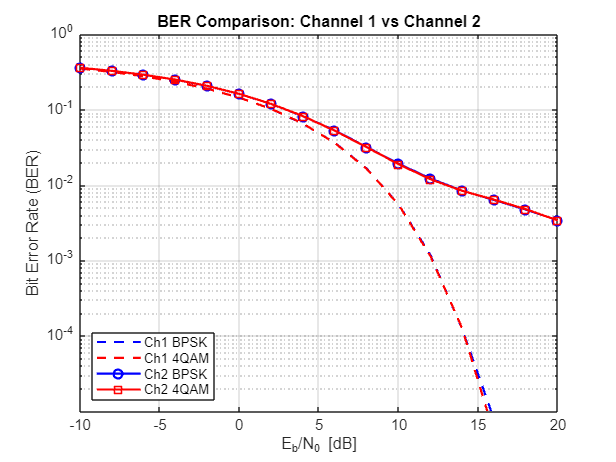



% -- Plot 2: Channel 1 vs Channel 2 (Sec 2.2.8) --
figure('Name', 'Channel 1 vs Channel 2 Performance');
% Channel 1 Curves (Dashed)
semilogy(EbN0_dB, BER_Ch1(1, :), 'b--', 'LineWidth', 1.5, 'DisplayName', 'Ch1 BPSK');
hold on;
semilogy(EbN0_dB, BER_Ch1(2, :), 'r--', 'LineWidth', 1.5, 'DisplayName', 'Ch1 4QAM');

% Channel 2 Curves (Solid)
semilogy(EbN0_dB, BER_Ch2(1, :), 'b-o', 'LineWidth', 1.5, 'DisplayName', 'Ch2 BPSK');
semilogy(EbN0_dB, BER_Ch2(2, :), 'r-s', 'LineWidth', 1.5, 'DisplayName', 'Ch2 4QAM');

grid on;
xlabel('E_b/N_0 [dB]');
ylabel('Bit Error Rate (BER)');
title('BER Comparison: Channel 1 vs Channel 2');
legend('Location', 'southwest');
ylim([1e-5 1]); % Set limit to see floor clearly if present
hold off

% 1. Load the data
data = readtable('C:\Users\yizha\qkd\FSOC\AO_simulation_log.csv')

% Revert the data to true energy in Joules
scale_factor = 3.9e9;
true_E = data.E_power_sum / scale_factor;
true_D = data.D_power_sum / scale_factor;
%% 2. Time-Interval Aggregation (Row-Based)
interval_size = 780; % ms
time_jump = 20;      % ms
rows_per_interval = interval_size / time_jump; % Exactly 39 rows per cycle

num_rows = height(data); 

% Group into chunks of 39 rows (1-39 -> Group 1, 40-78 -> Group 2, etc.)
group_indices = floor((0:num_rows-1) / rows_per_interval)' + 1; 

% Calculate the mean energy for each 39-row interval
mean_E = accumarray(group_indices, true_E, [], @mean);
mean_D = accumarray(group_indices, true_D, [], @mean);

%% 3. Define Noise Levels for the Sweep
% IMPORTANT: To see errors on the plot, your SNR needs to be between 0 and ~15 dB.
% We are creating an array of noise levels (in Joules) to sweep across.
% You may need to adjust the exponents (e.g., 1e-12 to 1e-10) based on your true energy.
noise_levels = logspace(-4, -1, 15);

data = 440×5 table
    timestep    E_power_sum    D_power_sum    num_airy    r0_ref
    ________    ___________    ___________    ________    ______

        0        9.118e+07      9.118e+07        2         0.01 
       20       9.5264e+07     3.1099e+08        2         0.01 
       40       9.8154e+07     3.0961e+08        2         0.01 
       60       9.6921e+07     3.0801e+08        2         0.01 
       80       9.3965e+07     3.0576e+08        2         0.01 
      100        9.273e+07     3.0488e+08        2         0.01 
      120       9.5062e+07     3.0324e+08        2         0.01 
      140       9.9722e+07     3.0264e+08        2         0.01 
      160       1.0467e+08      3.033e+08        2         0.01 
      180       1.0606e+08     3.0331e+08        2         0.01 
      200       1.1076e+08    


--- Diagnostic Info ---


Min SNR (E Channel): -4.68 dB


Max SNR (E Channel): 25.32 dB


Min SNR (D Channel): -1.02 dB


Max SNR (D Channel): 28.98 dB


Total bits simulated per noise level: 120000


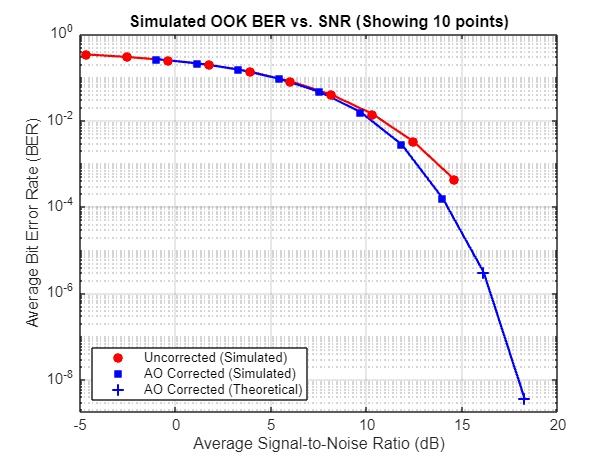

%% 4. Simulate and Calculate Averaged BER
% mod_scheme = 'OOK'; % Options: 'OOK' or 'BPSK' (We will add 'DPSK' and '4QAM' next)
mod_scheme = 'BPSK'; % Options: 'OOK' or 'BPSK' (We will add 'DPSK' and '4QAM' next)

num_bits = 1000; % Bits per interval
num_intervals = length(mean_E);
total_bits = num_bits * num_intervals; 

results = struct();
% Arrays to hold the simulated data
all_snr_E = zeros(1, length(noise_levels));
all_ber_E = zeros(1, length(noise_levels));
all_snr_D = zeros(1, length(noise_levels));
all_ber_D = zeros(1, length(noise_levels));

% Arrays to hold the theoretical data
all_theory_ber_E = zeros(1, length(noise_levels));
all_theory_ber_D = zeros(1, length(noise_levels));

for i = 1:length(noise_levels)
    current_noise = noise_levels(i);
    
    % Calculate exact SNR arrays for this specific noise level
    snr_E_dB_array = 10 * log10(mean_E ./ current_noise);
    snr_D_dB_array = 10 * log10(mean_D ./ current_noise);
    
    total_errors_e = 0;
    total_errors_d = 0;
    
    for j = 1:num_intervals
        % Generate random bits
        tx_bits_e = randi([0 1], num_bits, 1);
        tx_bits_d = randi([0 1], num_bits, 1);
        
        %% --- Modulation, Noise, and Demodulation ---
        switch mod_scheme
            case 'OOK'
                % E Channel (Uncorrected)
                rx_sig_e = awgn(tx_bits_e, snr_E_dB_array(j), 'measured'); 
                rx_bits_e = rx_sig_e > 0.5;
                
                % D Channel (AO Corrected)
                rx_sig_d = awgn(tx_bits_d, snr_D_dB_array(j), 'measured'); 
                rx_bits_d = rx_sig_d > 0.5;
                
            case 'BPSK'
                % Map bits: 0 -> -1, 1 -> +1
                tx_sym_e = 2*tx_bits_e - 1;
                tx_sym_d = 2*tx_bits_d - 1;
                
                % E Channel (Uncorrected)
                rx_sig_e = awgn(tx_sym_e, snr_E_dB_array(j), 'measured'); 
                rx_bits_e = rx_sig_e > 0; % Threshold is now 0
                
                % D Channel (AO Corrected)
                rx_sig_d = awgn(tx_sym_d, snr_D_dB_array(j), 'measured'); 
                rx_bits_d = rx_sig_d > 0; % Threshold is now 0
        end
        
        % Count Errors
        total_errors_e = total_errors_e + sum(tx_bits_e ~= rx_bits_e);
        total_errors_d = total_errors_d + sum(tx_bits_d ~= rx_bits_d);
    end
    
    % Store the average SNR for the x-axis
    all_snr_E(i) = mean(snr_E_dB_array);
    all_snr_D(i) = mean(snr_D_dB_array);
    
    % Store the overall simulated average BER
    all_ber_E(i) = total_errors_e / total_bits;
    all_ber_D(i) = total_errors_d / total_bits;
    
    %% --- Theoretical Average BER Calculation ---
    switch mod_scheme
        case 'OOK'
            all_theory_ber_E(i) = mean(0.5 * erfc(0.5 * sqrt(10.^(snr_E_dB_array / 10))));
            all_theory_ber_D(i) = mean(0.5 * erfc(0.5 * sqrt(10.^(snr_D_dB_array / 10))));
            
        case 'BPSK'
            all_theory_ber_E(i) = mean(0.5 * erfc(sqrt(10.^(snr_E_dB_array / 10))));
            all_theory_ber_D(i) = mean(0.5 * erfc(sqrt(10.^(snr_D_dB_array / 10))));
    end
end

%% 5. Diagnostics and Zero-Error Replacement
% Find where the simulation had exactly zero errors
is_zero_E = (all_ber_E == 0);
is_zero_D = (all_ber_D == 0);

% Replace those specific 0s with the calculated theoretical values
all_ber_E(is_zero_E) = all_theory_ber_E(is_zero_E);
all_ber_D(is_zero_D) = all_theory_ber_D(is_zero_D);

%% 6. Filter and Plot the Results

% --- NEW PARAMETER: Control how many points to plot ---
% Set this to the number of points you want to see, starting from the left side of the graph (lowest SNR).
num_points_to_plot = 10; 

% Ensure we don't accidentally request more points than exist
num_points_to_plot = min(num_points_to_plot, length(noise_levels));

% Sort the data so we always grab points from left to right on the graph
[~, sort_idx] = sort(all_snr_E, 'ascend');

% Apply the sorting and truncation to create plotting arrays
plot_idx = sort_idx(1:num_points_to_plot);

plot_snr_E = all_snr_E(plot_idx);
plot_ber_E = all_ber_E(plot_idx);
plot_snr_D = all_snr_D(plot_idx);
plot_ber_D = all_ber_D(plot_idx);

plot_is_zero_E = is_zero_E(plot_idx);
plot_is_zero_D = is_zero_D(plot_idx);

figure;
fprintf('\n--- Diagnostic Info ---\n');
fprintf('Min SNR (E Channel): %.2f dB\n', min(all_snr_E));
fprintf('Max SNR (E Channel): %.2f dB\n', max(all_snr_E));
fprintf('Min SNR (D Channel): %.2f dB\n', min(all_snr_D));
fprintf('Max SNR (D Channel): %.2f dB\n', max(all_snr_D));
fprintf('Total bits simulated per noise level: %d\n', total_bits);

% 1. Draw the continuous lines connecting ALL selected points
semilogy(plot_snr_E, plot_ber_E, '-r', 'LineWidth', 1.5, 'HandleVisibility', 'off');
hold on;
semilogy(plot_snr_D, plot_ber_D, '-b', 'LineWidth', 1.5, 'HandleVisibility', 'off');

% 2. Plot the SIMULATED points (Filled markers)
semilogy(plot_snr_E(~plot_is_zero_E), plot_ber_E(~plot_is_zero_E), 'ro', 'MarkerFaceColor', 'r', ...
    'DisplayName', 'Uncorrected (Simulated)');
semilogy(plot_snr_D(~plot_is_zero_D), plot_ber_D(~plot_is_zero_D), 'bs', 'MarkerFaceColor', 'b', ...
    'DisplayName', 'AO Corrected (Simulated)');

% 3. Plot the THEORETICAL replacement points (Distinct cross/plus markers)
semilogy(plot_snr_E(plot_is_zero_E), plot_ber_E(plot_is_zero_E), 'rx', 'MarkerSize', 8, 'LineWidth', 1.5, ...
    'DisplayName', 'Uncorrected (Theoretical)');
semilogy(plot_snr_D(plot_is_zero_D), plot_ber_D(plot_is_zero_D), 'b+', 'MarkerSize', 8, 'LineWidth', 1.5, ...
    'DisplayName', 'AO Corrected (Theoretical)');
hold off;

% Formatting
xlabel('Average Signal-to-Noise Ratio (dB)');
ylabel('Average Bit Error Rate (BER)');
title(sprintf('Simulated %s BER vs. SNR (Showing %d points)', mod_scheme, num_points_to_plot));
legend('Location', 'southwest');
grid on;

% Dynamic Y-axis limits depending on how low the truncated curves drop
ylim([min([plot_ber_E, plot_ber_D])/2, 1]);
hold off ;